close all
clear all

step = 0.2;
n = 21;
alpha = 2.5;
K = 23;
T = 100000;
beta = 1E-6;



% Pre-allocate matrices
sigma = 2 * rand(n) - 1; % random matrix with -1, 1
sigma = sigma * pi;
%sigma = flipud(sigma);

s3sum=0;


% Initial energy calculation
[P, S, E, sumdata] = compute_interactions(sigma, n, step, alpha, K, T);

eta1=0.55*randn(n,n);

S=S+eta1;

E(1)-E(2)

ans = 15.4825


E(T)

ans = 222.7309

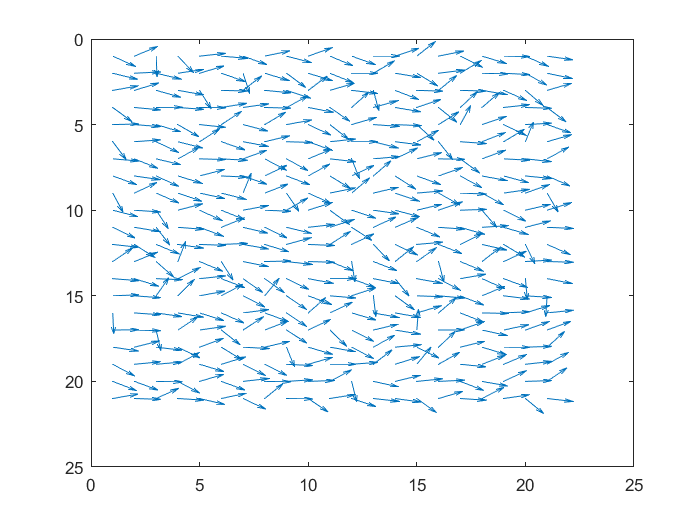


kasper=exp(-(E(1)-E(2)));


figure(1); quiver(cos(S),sin(S))
set (gca,'Ydir','reverse')



% Simulation data collection
SimData = flipud(S); 

% Save data
save('Simulation_data.mat', 'SimData');




function [P, S, E, sumdata, k, deltaE] = compute_interactions(sigma, n, step , alpha , K, T)



E = zeros(1, T+1);        % Sikrer, at E er allokeret til alle iterationer
deltaE = zeros(1, T+1);   % Sikrer, at deltaE er allokeret korrekt
sumdata = zeros(1, T+1);  % Sikrer, at sumdata er forudallokeret
 

for k=2:T+1
  
    R1 = randi([1, n]);
    R2 = randi([1, n]);   
    R3 = randi([1, n]);
    R4 = randi([1, n]);
    
    deltax = step*randn;
    
    % Flip a random spin
    if k>2
    sigma(R3, R4) = sigma(R3, R4) + deltax;
    end
    n = size(sigma, 1);
    Pa = zeros(n, n);
    Pb = zeros(n, n);
    Pc = zeros(n, n);
    Pd = zeros(n, n);
    Pe = zeros(n, n);
    
    
    % Calculate interaction terms
    Pa(2:end, :) = sigma(2:end, :) - sigma(1:end-1, :); %nearest neighbor up
    Pb(1:end-1, :) = sigma(1:end-1, :) - sigma(2:end, :); %nearest neighbor down
    Pc(:, 2:end) = sigma(:, 2:end) - sigma(:, 1:end-1); %nearest neighbor to the left
    Pd(:, 1:end-1) = sigma(:, 1:end-1) - sigma(:, 2:end); %nearest neighbor to the right
    
    
    %P = cos(2 * (Pa + Pb + Pc + Pd));
    P = Pa.^2 + Pb.^2 + Pc.^2 + Pd.^2;
    S = sigma;

    E(k) = K/4 * sum(P, "all") + K * alpha / 2 * sum(sigma(1, :).^2,"all");
    %E(k) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    
    if k==2
      
    sigma(R1, R2) = sigma(R1, R2) + deltax;
    
    Pa(2:end, :) = sigma(2:end, :) - sigma(1:end-1, :);
    Pb(1:end-1, :) = sigma(1:end-1, :) - sigma(2:end, :);
    Pc(:, 2:end) = sigma(:, 2:end) - sigma(:, 1:end-1);
    Pd(:, 1:end-1) = sigma(:, 1:end-1) - sigma(:, 2:end);
    
    
    %P = cos(2 * (Pa + Pb + Pc + Pd));
    P = Pa.^2 + Pb.^2 + Pc.^2 + Pd.^2;
    S = sigma;

    E(k-1) = K/4 * sum(P, "all") + K * alpha / 2 * sum(sigma(1, :).^2,"all");
    %E(k-1) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    deltaE(k) = E(k-1) - E(k);
    
    if rand < exp(-deltaE(k))
        E(k) = E(k)+deltaE(k);
    else
        % Revert the flip if energy does not decrease
        sigma(R1, R2) = sigma(R1, R2) - deltax;
    end
    end
    
    
    if k>2
    deltaE(k) = E(k) - E(k-1);
    
    if rand < exp(-deltaE(k))
        E(k)=E(k)+deltaE(k);
    else
        % Revert the flip if energy does not decrease
        sigma(R3, R4) = sigma(R3, R4) - deltax;
    end
    end
    Pa(2:end, :) = sigma(2:end, :) - sigma(1:end-1, :);
    Pb(1:end-1, :) = sigma(1:end-1, :) - sigma(2:end, :);
    Pc(:, 2:end) = sigma(:, 2:end) - sigma(:, 1:end-1);
    Pd(:, 1:end-1) = sigma(:, 1:end-1) - sigma(:, 2:end);
 
    
    %P = cos(2 * (Pa + Pb + Pc + Pd));
    P = Pa.^2 + Pb.^2 + Pc.^2 + Pd.^2;
    S = sigma;

    E(k) = K/4 * sum(P, "all") + K * alpha / 2 * sum(sigma(1, :).^2,"all");
    %E(k) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    sumdata(k)=sum(S,"all");
    deltaE(k) = E(k-1) - E(k);
end
end

